# Analysis of Glucose readings

## Objectives

Assessment of the agreement between fingerstick and lab analyzed glucose measurements.

A series of Bland-Altman plots were used to assess the agreement between the two testing types as a function of the time between the tests.

To assess if the frequency of fingerstick vs laboratory tests was associated with any admission, demographic or clinical patient features. 

## Prepare the data for this Live Script

#### Start using BigQuery:

- Upload to your BigQuery project the `ICUinputs` data-frame created in the [1.0-ara-data-curation-I.ipynb](https://github.com/MIT-LCP/mimic-code/tree/master/notebooks/ICUglycemia) notebook. You also have the option to upload manually the glucose_insulin_ICU.csv created in the same JUPYTER notebook.

- Perform the following query:

- Save the query as a CSV file to your Google Drive and go to the folder where it was saved (usually the folder name begins with `bq-results`).

- Rename the file as GlucoseReadingsCurated.csv and download it to your local hard disk.

- Follow the instructions described in FINAL PREPARATION.

#### Directly from the [1.0-ara-data-curation-I.ipynb](https://github.com/MIT-LCP/mimic-code/tree/master/notebooks/ICUglycemia) notebook:

- Create the data-frame `GlucoseReadingsCurated` in the 1.0-ara-data-curation-I.ipynb notebook as follows:

- Save the data-frame as CSV in your hard drive.

- Follow the instructions described in FINAL PREPARATION.

### Final preparation

- Open the CSV file on Microsoft's Excel.

- In case the columns `ICU_ADMISSIONTIME`, `ICU_DISCHARGETIME` and `GLCTIMER `do not have the date-tiem format YYYY-MM-DD HH:mm:ss or MM/DD/YYYY  HH:mm:ss, use the function REPLACE and erase manually the UTC or +00:00.

- Change the name of the sheet to GlucoseReadingsCurated and save the spreadsheet as a XLSX file in the folder where you saved this Live Script.

- Run this script. Make sure you also saved the functions (folder Functions in GitHub).

## Assessment of fingerstick and lab analyzer agreement

Assessment of the agreement between fingerstick and lab analyzed glucose measurements was done by identifying the first fingerstick glucose test during the ICU stay and pairing it with the lab analyzed test closest temporally to this fingerstick test.  These pairs were stratified by the duration of time between the two measurements, and resulted in 11,904 pairs of fingerstick – lab analyzer readings. It is important to demonstrate the independence in each entry. Following a normal distribution is important, but demonstrating independence in each sample has more relevance.

% Import data
% Make sure the CSV file contains the following columns:
% SUBJECT_ID, HADM_ID, ICUSTAY_ID, ICU_ADMISSIONTIME, ICU_DISCHARGETIME, GLCTIMER, 
% GLC, GLCSOURCE
GlucoseReadingsCurated = import_GLC_cur("GlucoseReadingsCurated.xlsx", ...
    "GlucoseReadingsCurated", [2, 458085]);

% Estimate LOS
t1=table2array(GlucoseReadingsCurated(:,{'ICU_DISCHARGETIME'}));
t2=table2array(GlucoseReadingsCurated(:,{'ICU_ADMISSIONTIME'}));
dt_days=array2table(between(t2,t1,'Days'),"VariableNames",{'LOS_days'});
dt_min=array2table(duration(time(between(t2,t1,'time')),'Format','m'), ...
    "VariableNames",{'LOS_min'});
GlucoseReadingsCurated = horzcat(GlucoseReadingsCurated,dt_days,dt_min);

% Split into fingerstick and serum glucose
serum_icu = GlucoseReadingsCurated(ismissing(GlucoseReadingsCurated.GLCSOURCE,'BLOOD'),:);
finger_icu = GlucoseReadingsCurated(~ismissing(GlucoseReadingsCurated.GLCSOURCE,'BLOOD'),:);

% Select first reading per method

uniqueICU = unique(GlucoseReadingsCurated.ICUSTAY_ID);

first_readings = array2table(nan(length(uniqueICU),13));
first_readings.Properties.VariableNames = {'ICUSTAY_ID','ICU_ADMISSIONTIME',...
    'ICU_DISCHARGETIME','GLCTIMER_f_1st','GLC_f_1st', 'GLCTIMER_s_1st','GLC_s_1st',...
    'LOS_min','count_f','count_s','GLC_m_f','GLC_m_s','time_gap'};

for i=1:length(uniqueICU)
    ICUstay = uniqueICU(i);
    idx_finger = finger_icu.ICUSTAY_ID == ICUstay;
    idx_serum = serum_icu.ICUSTAY_ID == ICUstay;
    
    % ICU stay
    first_readings(i,'ICUSTAY_ID') = array2table(ICUstay);
    
    % Fingertick readings
    tbl_finger = finger_icu(idx_finger,:);
    
    % Serum glucose readings
    tbl_serum = serum_icu(idx_serum,:);
    
    if isempty(tbl_finger)
        disp(['No any fingerstick for ICU stay: ',num2str(ICUstay)])
        
        % Redefine glucose_row
        glucose_row = topkrows(tbl_serum,1,{'GLCTIMER'},'ascend');
        first_readings(i,'count_s') = array2table(size(tbl_serum,1));
        first_readings(i,'GLC_m_s') = array2table(mean(tbl_serum.GLC,'omitnan'));
        
        % Fingerstick value and timestamp does not exist.
        first_readings(i,'GLC_f_1st') = array2table(nan);
        first_readings(i,'GLCTIMER_f_1st') = array2table(datenum(NaT));
        first_readings(i,'count_f') = array2table(0);
        first_readings(i,'GLC_m_f') = array2table(0);
    else
        glucose_row = topkrows(tbl_finger,1,{'GLCTIMER'},'ascend');
        
        % Glucose timer from fingerstick exist
        first_readings(i,'GLCTIMER_f_1st') = array2table(datenum(glucose_row.GLCTIMER));
        % Glucose reading value from fingerstick exist
        first_readings(i,'GLC_f_1st') = array2table(glucose_row.GLC);
        first_readings(i,'count_f') = array2table(size(tbl_finger,1));
        first_readings(i,'GLC_m_f') = array2table(mean(tbl_finger.GLC,'omitnan'));
    end
   
    if ~isempty(tbl_serum)
        % Find the serum glucose reading closest to the fingerstick reading
        [time_gap,min_serum]=min(table2array(tbl_serum(:,{'GLCTIMER'}))-glucose_row.GLCTIMER);
        % Glucose reading from serum
        first_readings(i,'GLC_s_1st') = tbl_serum(min_serum,"GLC");
        % Serum's glucose reading datetime
        first_readings(i,"GLCTIMER_s_1st") = array2table(datenum(table2array(tbl_serum(min_serum,'GLCTIMER'))));
        first_readings(i,'count_s') = array2table(size(tbl_serum,1));
        first_readings(i,'GLC_m_s') = array2table(mean(tbl_serum.GLC,'omitnan'));
        first_readings(i,'time_gap') = array2table(minutes(time_gap));
    else
        disp(['No serum glucose reading for ICU stay: ',num2str(ICUstay)])
        
        % Serum glucose reading do not exist
        first_readings(i,'GLC_s_1st') = array2table(nan);
        first_readings(i,'GLCTIMER_s_1st') = array2table(datenum(NaT));
        first_readings(i,'count_s') = array2table(0);
        first_readings(i,'GLC_m_s') = array2table(0);
    end
    
    % In case there is no any information
    if isempty(glucose_row)
        disp(['No glucose readings for ICU stay: ',num2str(ICUstay)])
        % Admission time
        first_readings(i,'ICU_ADMISSIONTIME') = array2table(nan);
        % Discharge time
        first_readings(i,'ICU_DISCHARGETIME') = array2table(datenum(NaT));
    else
        % Admission time
        first_readings(i,'ICU_ADMISSIONTIME') = array2table(datenum(glucose_row.ICU_ADMISSIONTIME));
        % Discharge time
        first_readings(i,'ICU_DISCHARGETIME') = array2table(datenum(glucose_row.ICU_DISCHARGETIME));
    end
    
    % Length of stay in minutes
    first_readings(i,'LOS_min') = array2table(datenum(glucose_row.LOS_min));
end

No serum glucose reading for ICU stay: 200024


No any fingerstick for ICU stay: 200163


No serum glucose reading for ICU stay: 200746
No serum glucose reading for ICU stay: 201883
No serum glucose reading for ICU stay: 204241


No any fingerstick for ICU stay: 204347
No any fingerstick for ICU stay: 204372
No any fingerstick for ICU stay: 204521
No any fingerstick for ICU stay: 204840
No any fingerstick for ICU stay: 205302
No any fingerstick for ICU stay: 205338


No serum glucose reading for ICU stay: 205362


No any fingerstick for ICU stay: 205414
No any fingerstick for ICU stay: 205827
No any fingerstick for ICU stay: 206464


No serum glucose reading for ICU stay: 207401


No any fingerstick for ICU stay: 208230
No any fingerstick for ICU stay: 208406


No serum glucose reading for ICU stay: 208514


No any fingerstick for ICU stay: 208590
No any fingerstick for ICU stay: 209206
No any fingerstick for ICU stay: 209598
No any fingerstick for ICU stay: 210014
No any fingerstick for ICU stay: 210335
No any fingerstick for ICU stay: 210463
No any fingerstick for ICU stay: 210628
No any fingerstick for ICU stay: 210776


No serum glucose reading for ICU stay: 210875
No serum glucose reading for ICU stay: 211562


No any fingerstick for ICU stay: 211977
No any fingerstick for ICU stay: 212477
No any fingerstick for ICU stay: 212857
No any fingerstick for ICU stay: 213039


No serum glucose reading for ICU stay: 213468
No serum glucose reading for ICU stay: 214221


No any fingerstick for ICU stay: 214341
No any fingerstick for ICU stay: 214630
No any fingerstick for ICU stay: 215361


No serum glucose reading for ICU stay: 216358
No serum glucose reading for ICU stay: 216618


No any fingerstick for ICU stay: 216870
No any fingerstick for ICU stay: 217050
No any fingerstick for ICU stay: 217208


No serum glucose reading for ICU stay: 217632
No serum glucose reading for ICU stay: 217733
No serum glucose reading for ICU stay: 217863
No serum glucose reading for ICU stay: 217920


No any fingerstick for ICU stay: 218716
No any fingerstick for ICU stay: 219128
No any fingerstick for ICU stay: 219447


No serum glucose reading for ICU stay: 221213
No serum glucose reading for ICU stay: 221647
No serum glucose reading for ICU stay: 222238


No any fingerstick for ICU stay: 223042


No serum glucose reading for ICU stay: 223110
No serum glucose reading for ICU stay: 223259


No any fingerstick for ICU stay: 223336
No any fingerstick for ICU stay: 223360
No any fingerstick for ICU stay: 223510
No any fingerstick for ICU stay: 223926
No any fingerstick for ICU stay: 224025


No serum glucose reading for ICU stay: 224079
No serum glucose reading for ICU stay: 224742


No any fingerstick for ICU stay: 225021
No any fingerstick for ICU stay: 225918
No any fingerstick for ICU stay: 226179
No any fingerstick for ICU stay: 226466
No any fingerstick for ICU stay: 226487


No serum glucose reading for ICU stay: 227378


No any fingerstick for ICU stay: 227522
No any fingerstick for ICU stay: 227528
No any fingerstick for ICU stay: 227907
No any fingerstick for ICU stay: 227942
No any fingerstick for ICU stay: 227970
No any fingerstick for ICU stay: 228056
No any fingerstick for ICU stay: 228086
No any fingerstick for ICU stay: 228492


No serum glucose reading for ICU stay: 228667
No serum glucose reading for ICU stay: 228908


No any fingerstick for ICU stay: 229035
No any fingerstick for ICU stay: 229140


No serum glucose reading for ICU stay: 229635


No any fingerstick for ICU stay: 229763
No any fingerstick for ICU stay: 229790
No any fingerstick for ICU stay: 229850
No any fingerstick for ICU stay: 230852


No serum glucose reading for ICU stay: 231220


No any fingerstick for ICU stay: 231470
No any fingerstick for ICU stay: 231576
No any fingerstick for ICU stay: 231745
No any fingerstick for ICU stay: 231920


No serum glucose reading for ICU stay: 232091
No serum glucose reading for ICU stay: 232563
No serum glucose reading for ICU stay: 232956
No serum glucose reading for ICU stay: 233085


No any fingerstick for ICU stay: 233253
No any fingerstick for ICU stay: 233654


No serum glucose reading for ICU stay: 234310


No any fingerstick for ICU stay: 234375


No serum glucose reading for ICU stay: 234385


No any fingerstick for ICU stay: 235479
No any fingerstick for ICU stay: 235657
No any fingerstick for ICU stay: 235710


No serum glucose reading for ICU stay: 235724
No serum glucose reading for ICU stay: 236368
No serum glucose reading for ICU stay: 236623


No any fingerstick for ICU stay: 237472
No any fingerstick for ICU stay: 237515
No any fingerstick for ICU stay: 237549
No any fingerstick for ICU stay: 237609


No serum glucose reading for ICU stay: 238215


No any fingerstick for ICU stay: 238796
No any fingerstick for ICU stay: 239130


No serum glucose reading for ICU stay: 239424
No serum glucose reading for ICU stay: 239610


No any fingerstick for ICU stay: 241087


No serum glucose reading for ICU stay: 241264


No any fingerstick for ICU stay: 241759
No any fingerstick for ICU stay: 242144
No any fingerstick for ICU stay: 243088


No serum glucose reading for ICU stay: 243483
No serum glucose reading for ICU stay: 243526


No any fingerstick for ICU stay: 243854
No any fingerstick for ICU stay: 244380
No any fingerstick for ICU stay: 244743


No serum glucose reading for ICU stay: 244842
No serum glucose reading for ICU stay: 244924


No any fingerstick for ICU stay: 245728


No serum glucose reading for ICU stay: 245788
No serum glucose reading for ICU stay: 245959
No serum glucose reading for ICU stay: 245999


No any fingerstick for ICU stay: 246226
No any fingerstick for ICU stay: 246688


No serum glucose reading for ICU stay: 246873
No serum glucose reading for ICU stay: 246991


No any fingerstick for ICU stay: 247304


No serum glucose reading for ICU stay: 247485


No any fingerstick for ICU stay: 247634


No serum glucose reading for ICU stay: 247700
No serum glucose reading for ICU stay: 247704


No any fingerstick for ICU stay: 247716


No serum glucose reading for ICU stay: 247932
No serum glucose reading for ICU stay: 248410


No any fingerstick for ICU stay: 248748
No any fingerstick for ICU stay: 250011
No any fingerstick for ICU stay: 250129
No any fingerstick for ICU stay: 250216


No serum glucose reading for ICU stay: 250489


No any fingerstick for ICU stay: 250993
No any fingerstick for ICU stay: 250996
No any fingerstick for ICU stay: 251033


No serum glucose reading for ICU stay: 251037


No any fingerstick for ICU stay: 251042


No serum glucose reading for ICU stay: 251526


No any fingerstick for ICU stay: 251581


No serum glucose reading for ICU stay: 251721


No any fingerstick for ICU stay: 251761
No any fingerstick for ICU stay: 252073


No serum glucose reading for ICU stay: 252299
No serum glucose reading for ICU stay: 252561


No any fingerstick for ICU stay: 252694
No any fingerstick for ICU stay: 253230


No serum glucose reading for ICU stay: 253461


No any fingerstick for ICU stay: 253567
No any fingerstick for ICU stay: 253638
No any fingerstick for ICU stay: 253703
No any fingerstick for ICU stay: 253725


No serum glucose reading for ICU stay: 253994


No any fingerstick for ICU stay: 254675
No any fingerstick for ICU stay: 255445


No serum glucose reading for ICU stay: 255553


No any fingerstick for ICU stay: 256572
No any fingerstick for ICU stay: 256727
No any fingerstick for ICU stay: 256746


No serum glucose reading for ICU stay: 258818


No any fingerstick for ICU stay: 260082
No any fingerstick for ICU stay: 260126
No any fingerstick for ICU stay: 260141


No serum glucose reading for ICU stay: 260388


No any fingerstick for ICU stay: 261310
No any fingerstick for ICU stay: 261332


No serum glucose reading for ICU stay: 261370


No any fingerstick for ICU stay: 261445


No serum glucose reading for ICU stay: 261740
No serum glucose reading for ICU stay: 261745


No any fingerstick for ICU stay: 262397
No any fingerstick for ICU stay: 262682


No serum glucose reading for ICU stay: 262694


No any fingerstick for ICU stay: 262948
No any fingerstick for ICU stay: 263500


No serum glucose reading for ICU stay: 263576
No serum glucose reading for ICU stay: 263747


No any fingerstick for ICU stay: 264359
No any fingerstick for ICU stay: 264614
No any fingerstick for ICU stay: 265286
No any fingerstick for ICU stay: 265402


No serum glucose reading for ICU stay: 265555


No any fingerstick for ICU stay: 265823


No serum glucose reading for ICU stay: 265918
No serum glucose reading for ICU stay: 266197


No any fingerstick for ICU stay: 266337
No any fingerstick for ICU stay: 266608
No any fingerstick for ICU stay: 266787


No serum glucose reading for ICU stay: 267692
No serum glucose reading for ICU stay: 267830


No any fingerstick for ICU stay: 268481
No any fingerstick for ICU stay: 268723


No serum glucose reading for ICU stay: 268787
No serum glucose reading for ICU stay: 268948


No any fingerstick for ICU stay: 269681


No serum glucose reading for ICU stay: 270097


No any fingerstick for ICU stay: 270186
No any fingerstick for ICU stay: 270201
No any fingerstick for ICU stay: 270204


No serum glucose reading for ICU stay: 270312


No any fingerstick for ICU stay: 270641


No serum glucose reading for ICU stay: 271245


No any fingerstick for ICU stay: 271350
No any fingerstick for ICU stay: 271962


No serum glucose reading for ICU stay: 272133
No serum glucose reading for ICU stay: 272695
No serum glucose reading for ICU stay: 272847


No any fingerstick for ICU stay: 273142
No any fingerstick for ICU stay: 273198
No any fingerstick for ICU stay: 273369
No any fingerstick for ICU stay: 273656
No any fingerstick for ICU stay: 273879


No serum glucose reading for ICU stay: 273985


No any fingerstick for ICU stay: 274258


No serum glucose reading for ICU stay: 274348


No any fingerstick for ICU stay: 274567
No any fingerstick for ICU stay: 274687
No any fingerstick for ICU stay: 275112


No serum glucose reading for ICU stay: 275287


No any fingerstick for ICU stay: 275353
No any fingerstick for ICU stay: 275365
No any fingerstick for ICU stay: 275443


No serum glucose reading for ICU stay: 275585


No any fingerstick for ICU stay: 275664
No any fingerstick for ICU stay: 275935
No any fingerstick for ICU stay: 277074


No serum glucose reading for ICU stay: 277949


No any fingerstick for ICU stay: 278204
No any fingerstick for ICU stay: 278567


No serum glucose reading for ICU stay: 278876


No any fingerstick for ICU stay: 279154
No any fingerstick for ICU stay: 279175


No serum glucose reading for ICU stay: 279392
No serum glucose reading for ICU stay: 279422
No serum glucose reading for ICU stay: 280074
No serum glucose reading for ICU stay: 280186


No any fingerstick for ICU stay: 280419


No serum glucose reading for ICU stay: 280799
No serum glucose reading for ICU stay: 281270
No serum glucose reading for ICU stay: 281374


No any fingerstick for ICU stay: 281453
No any fingerstick for ICU stay: 282422
No any fingerstick for ICU stay: 282467


No serum glucose reading for ICU stay: 282822


No any fingerstick for ICU stay: 283178
No any fingerstick for ICU stay: 283296
No any fingerstick for ICU stay: 283340


No serum glucose reading for ICU stay: 283845
No serum glucose reading for ICU stay: 285021
No serum glucose reading for ICU stay: 285206


No any fingerstick for ICU stay: 286379
No any fingerstick for ICU stay: 286488
No any fingerstick for ICU stay: 286550


No serum glucose reading for ICU stay: 287495


No any fingerstick for ICU stay: 287526
No any fingerstick for ICU stay: 287882
No any fingerstick for ICU stay: 288321


No serum glucose reading for ICU stay: 288355


No any fingerstick for ICU stay: 288586
No any fingerstick for ICU stay: 289786
No any fingerstick for ICU stay: 290175
No any fingerstick for ICU stay: 290284


No serum glucose reading for ICU stay: 290623


No any fingerstick for ICU stay: 290713
No any fingerstick for ICU stay: 290901


No serum glucose reading for ICU stay: 291026


No any fingerstick for ICU stay: 291080
No any fingerstick for ICU stay: 291602


No serum glucose reading for ICU stay: 291700


No any fingerstick for ICU stay: 291754


No serum glucose reading for ICU stay: 291931


No any fingerstick for ICU stay: 291971


No serum glucose reading for ICU stay: 292475
No serum glucose reading for ICU stay: 292639


No any fingerstick for ICU stay: 293554
No any fingerstick for ICU stay: 293616


No serum glucose reading for ICU stay: 293872
No serum glucose reading for ICU stay: 294580


No any fingerstick for ICU stay: 294807
No any fingerstick for ICU stay: 295745
No any fingerstick for ICU stay: 295773


No serum glucose reading for ICU stay: 296271


No any fingerstick for ICU stay: 296324
No any fingerstick for ICU stay: 297308
No any fingerstick for ICU stay: 297872
No any fingerstick for ICU stay: 298135


No serum glucose reading for ICU stay: 298759


No any fingerstick for ICU stay: 299208
No any fingerstick for ICU stay: 299572


No serum glucose reading for ICU stay: 299674


No any fingerstick for ICU stay: 299697


clearvars glucose_row idx_finger idx_serum tbl_serum tbl_finger

Missing data removal

disp(['Entries before removal of missing data: ',...
    num2str(size(first_readings,1))])

Entries before removal of missing data: 12210


first_readings = first_readings(~any(ismissing(first_readings,nan),2),:);
disp(['Entries after removal of missing data: ',...
    num2str(size(first_readings,1))])

Entries after removal of missing data: 11904


Compute the aritmetic substraction between finger and serum glucose ($\Delta$ GLC)

% Difference only between glucose readings
d_glc = first_readings.GLC_f_1st-first_readings.GLC_s_1st;
disp(['Mean: ',num2str(mean(d_glc),'%0.2f'),' +/- ',num2str(std(d_glc),'%0.2f')]);

Mean: 11.80 +/- 63.59


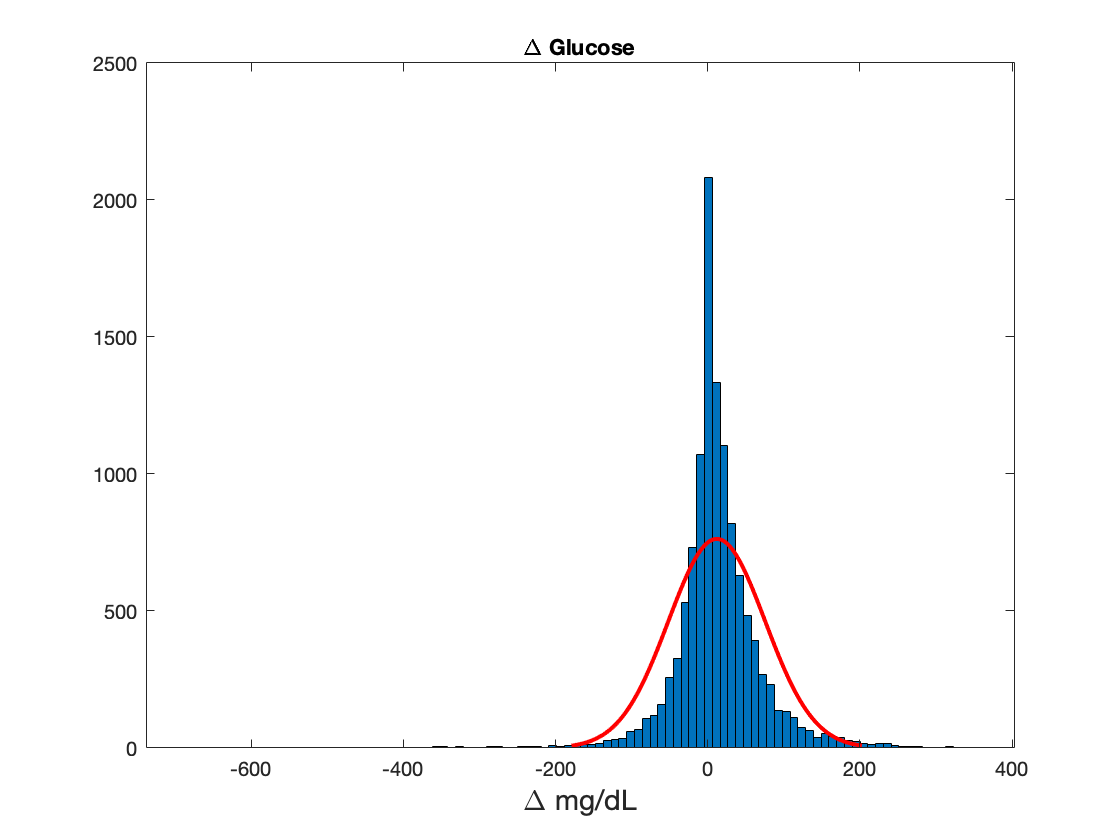

figure; 
histfit(d_glc)
title('\Delta Glucose')
xlabel('\Delta mg/dL', 'FontSize',14)

% Mean(Fingerstick - Serum)
d_mean = (first_readings.GLC_f_1st+first_readings.GLC_s_1st)./2;
% (Fingerstick-Serum)/d_mean
d_glc_mean = (first_readings.GLC_f_1st-first_readings.GLC_s_1st)./mean(first_readings.GLC_f_1st+first_readings.GLC_s_1st);

Histogram of time gaps between fingerstick and serum glucose

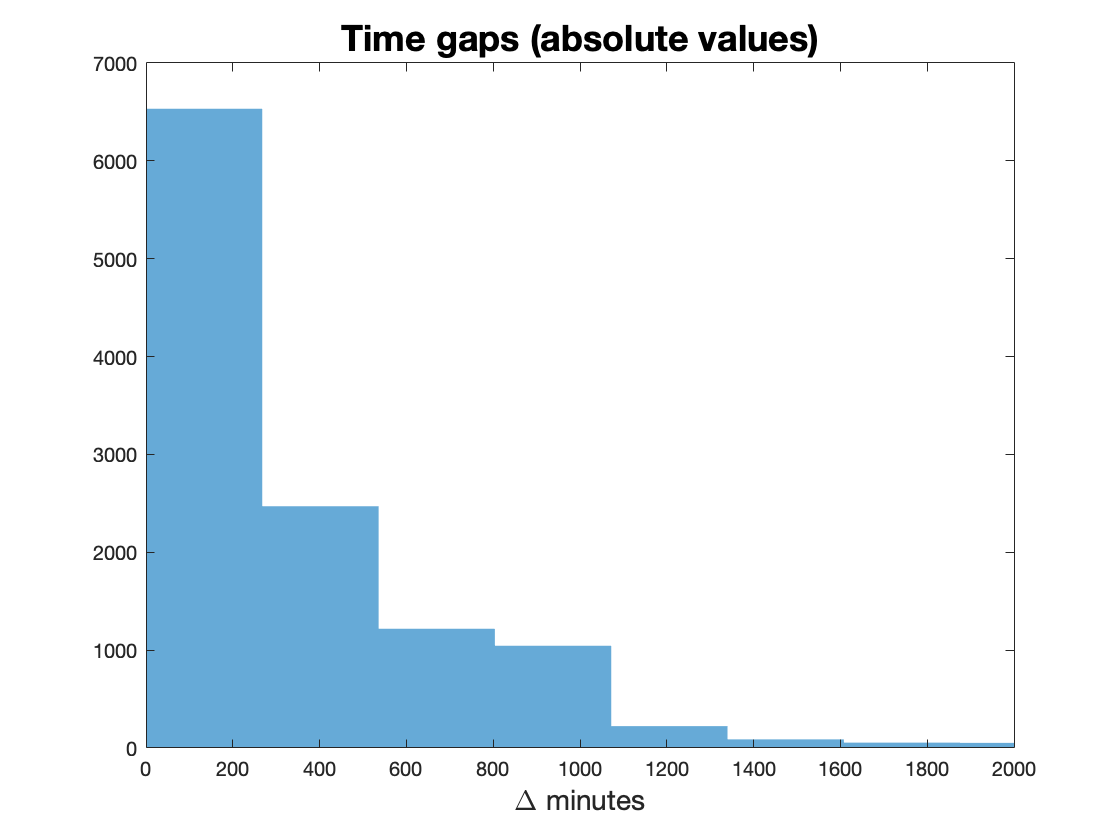

histogram(abs(first_readings.time_gap),100,'EdgeAlpha',0);
xlim([0 2000])
title('Time gaps (absolute values)','FontSize',18)
xlabel('\Delta minutes', 'FontSize',14)

### Hypothesis testing and Bland Altman analysis

A series of Bland-Altman plots were used to assess the agreement between the two testing types as a function of the time between the tests. The graphs are further complemented with a locally weighted scatter plot smooth (LOWESS) for glucose as the mean of the paired fingerstick-lab analyzed values increases.

**Wilcoxon Signed Rank Test**

It is a nonparametric test for two populations when the observations are paired. In this case, the test statistic, `W`, is the sum of the ranks of positive differences between the observations in the two samples (that is, `x`* – *`y`). When you use the test for one sample, then `W` is the sum of the ranks of positive differences between the observations and the hypothesized median value $M_0$.

theta_array = [30 60 120];

CIdata = nan(5,length(theta_array)+1);

bland = nan(8,length(theta_array)+1);

for i=1:(length(theta_array)+1)
    if i==1
        theta1 = 0;
        theta2 = theta_array(i);
    else
        if i==(length(theta_array)+1)
            theta1 = theta_array(i-1);
            theta2 = max(abs(first_readings.time_gap))+1;
        else
            theta1 = theta_array(i-1);
            theta2 = theta_array(i);
        end
    end
    theta = (abs(first_readings.time_gap)>=theta1)&(abs(first_readings.time_gap)<theta2);
    
    % Paired Wilcoxon rank test
    % Within +/- theta min
    [p,h,stats] = signrank(d_glc(theta));
    disp('Wilcoxon rank test')
    disp(['[Glucose fingerstick] - [Glucose serum] within ',...
        num2str(theta1),'-',num2str(theta2),' min',newline,...
        'Rejects Ho at the 5% significance level: ', ...
        num2str(h),newline,'p-value = ', num2str(p,'%0.2e'),...
        ', W statistic = ', num2str(stats.signedrank,'%0.2f')])
    disp(['Median: ', num2str(median(d_glc(theta)))]);
    disp(['Q1: ', num2str(quantile(d_glc(theta),0.25)), ...
        newline, ...
        'Q3: ', num2str(quantile(d_glc(theta),0.75)),newline]);
    N = length(d_glc(theta));
    disp(['Entries for ',num2str(theta1),'-',num2str(theta2),' min: ', ...
        num2str(N),newline,...
        num2str((N/(length(d_glc))*100),2),...
        '% of total entries',newline,' '])
    
    % Compute ‘Standard Error Of The Mean’ Of 
    % All Experiments At Each time gap
    ySEM = std(d_glc(theta))/sqrt(N);
    
    % Calculate 95% Probability Intervals Of 
    % t-Distribution
    CI95 = tinv([0.025 0.975], N-1);
    
    % Calculate 95% Confidence Intervals Of 
    % All Experiments At Each time gap
    yCI95 = bsxfun(@times, ySEM, CI95(:));
    
    % Allocate data
    CIdata(1:2,i) = yCI95;
    % Mean
    CIdata(3,i) = mean(d_glc(theta));
    % SD
    CIdata(4,i) = std(d_glc(theta));
    % N
    CIdata(5,i) = N;
    
    % Bland Altman analysis
    bland(1,i) = mean(d_glc(theta));
    bland(2,i) = std(d_glc(theta));
    
    % Limits of agreement
    % Lower
    lower = mean(d_glc(theta))-1.96*(std(d_glc(theta)));
        % SE
    SE = sqrt((3*(lower^2))/(N));
    yCI95 = bsxfun(@times, SE, CI95(:));
    
    bland(3,i) = lower;
    bland(4:5,i) = yCI95;
    
    % Upper
    upper = mean(d_glc(theta))+1.96*(std(d_glc(theta)));
        % SE
    SE = sqrt((3*(upper^2))/(N));
    yCI95 = bsxfun(@times, SE, CI95(:));
    
    bland(6,i) = upper;
    bland(7:8,i) = yCI95;
    
    clearvars SE lower upper yCI95
    
    % Title
    if i == (length(theta_array)+1)
        tlt = ['Over ',num2str(theta1), ' min'];
    else
        tlt = [num2str(theta1),' to ',num2str(theta2),' min'];
    end
    
    subplot(2,2,i)
    hold on
    scatter(d_mean(theta),d_glc(theta),3,'MarkerEdgeColor',[0 0.6 0.6],...
        'MarkerFaceColor',[0 .7 .7],'LineWidth',0.5,...
        'MarkerFaceAlpha',0.5,'MarkerEdgeAlpha',0.5)
    % MEAN
    a = yline(bland(1,i),'-',['MEAN = ',num2str(bland(1,i),'%.1f')],...
        'LineWidth',2.5,'Color',[0.9290 0.6940 0.1250],...
        'LabelVerticalAlignment','middle','FontWeight','bold');
    set(get(get(a,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    % SMOOTHING
    tmp_array = [d_mean(theta) d_glc(theta)];
    tmp_array = sortrows(tmp_array,1);
    f = smoothdata(tmp_array(:,2),'lowess',150);
    tmp_array = [tmp_array f];
    plot(tmp_array(:,1),tmp_array(:,3),"LineStyle",'-',...
        "LineWidth",2,"Color",'#7E2F8E');
    % UPPER LIMIT
    b = yline(bland(6,i),'--',['+1.96SD = ',num2str(bland(6,i),'%.1f')],...
        'LineWidth',2,'Color',[0.6350 0.0780 0.1840],...
        'LabelVerticalAlignment','top','FontWeight','bold');
    set(get(get(b,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    % LOWER LIMIT
    d = yline(bland(3,i),'--',['-1.96SD = ',num2str(bland(3,i),'%.1f')],...
        'LineWidth',2,'Color',[0.6350 0.0780 0.1840],...
        'LabelVerticalAlignment','bottom','FontWeight','bold');
    set(get(get(d,'Annotation'),'LegendInformation'),'IconDisplayStyle','off');
    hold off
    xlabel('Mean of both tests',"FontSize",16, "FontWeight","bold")
    ylabel('\Delta glucose (mg/dL)', 'FontSize',16, "FontWeight","bold")
    title(tlt,'FontSize',16, "FontWeight","bold")
    xlim([0 max(d_mean)+79])
    ylim([-400 400])
    ax = gca;
    ax.FontSize = 14;
    
    clearvars a b d h f tmp_array ySEM N ax
   
end

Wilcoxon rank test


[Glucose fingerstick] - [Glucose serum] within 0-30 min
Rejects Ho at the 5% significance level: 1
p-value = 2.44e-02, W statistic = 734146.50


Median: 2


Q1: -17
Q3: 21



Entries for 0-30 min: 1683
14% of total entries
 


Wilcoxon rank test


[Glucose fingerstick] - [Glucose serum] within 30-60 min
Rejects Ho at the 5% significance level: 1
p-value = 1.78e-21, W statistic = 236584.00


Median: 4


Q1: -4
Q3: 26



Entries for 30-60 min: 985
8.3% of total entries
 


Wilcoxon rank test


[Glucose fingerstick] - [Glucose serum] within 60-120 min
Rejects Ho at the 5% significance level: 1
p-value = 7.01e-16, W statistic = 447156.50


Median: 0


Q1: -2
Q3: 18



Entries for 60-120 min: 1860
16% of total entries
 


Wilcoxon rank test


[Glucose fingerstick] - [Glucose serum] within 120-26748 min
Rejects Ho at the 5% significance level: 1
p-value = 1.95e-152, W statistic = 18022954.00


Median: 13


Q1: -13
Q3: 44.5



Entries for 120-26748 min: 7376
62% of total entries
 


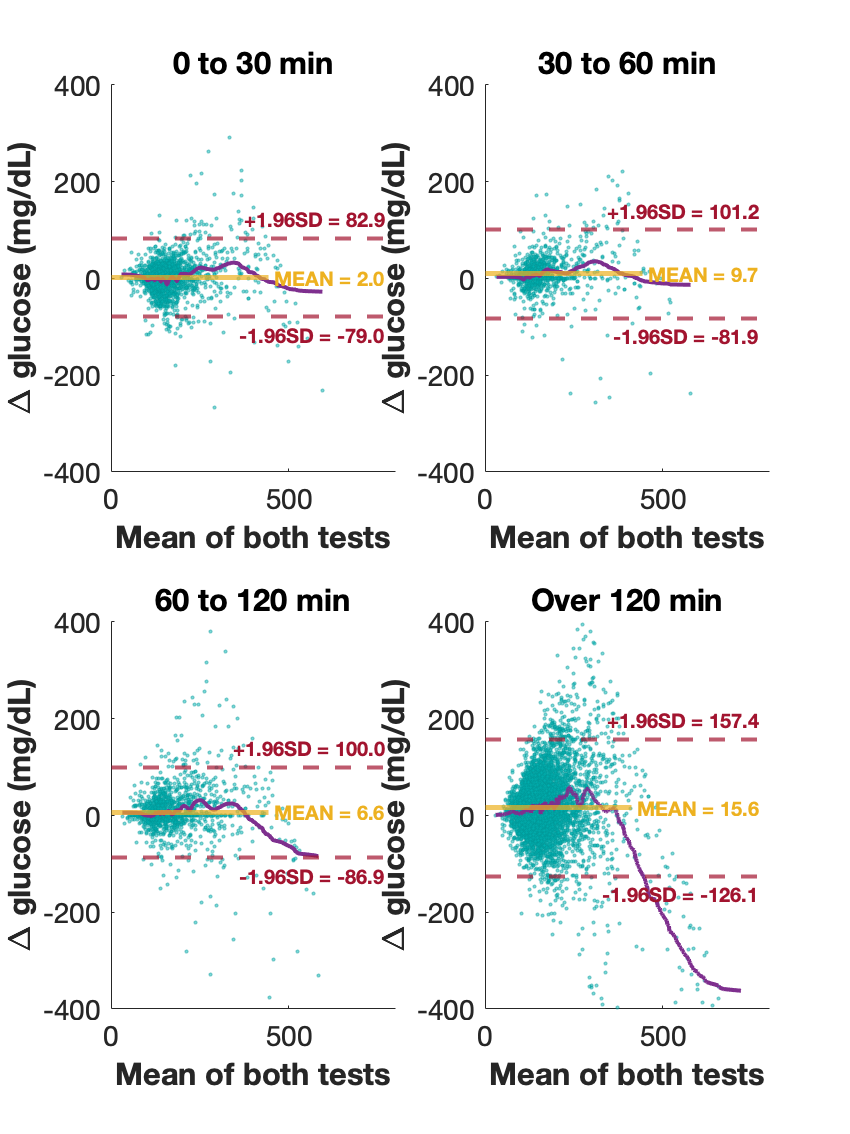

fig = gcf;
fig.Units = "centimeters";
fig.Position(3) = 15;
fig.Position(4) = 20;
print(fig,'Bland-Altman','-depsc')

## Regression Analysis

We assessed if the frequency of fingerstick vs laboratory tests was associated with any admission, demographic or clinical patient features.  A multivariable logistic regression model was fit to identify covariates that with an ICU admission having a higher number of bedside fingerstick readings over samples analyzed in the laboratory. Covariates were patient’s age at admission, ICU admission type, ethnicity, gender, SOFA score, and diabetes condition.

### Import input features ($\textbf{x} = x_1, \dots , x_n$)

`Admissions` table comes from:

% Import admissions table
admissions = import_admissions("admissions.xlsx", "admissions", [2, 61052]);
disp(['Entries: ', num2str(size(admissions,1))])

Entries: 61051


`SOFA` table comes from:

% Import SOFA scores
SOFA = import_SOFA("SOFA.xlsx", "SOFA", [2, 61533]);
disp(['Entries: ', num2str(size(SOFA,1))])

Entries: 61532


diabetes table comes from:

% Import diabetes
diabetes = importDiabetes("diabetes.xlsx", "DIABETES", [2, 61052]);
disp(['Entries: ', num2str(size(diabetes,1))])

Entries: 61051


% Inner join admissions and glucose readings
Tleft = horzcat(first_readings,array2table(d_glc,"VariableNames",{'d_glc'}));
Tright = admissions(:,{'ICUSTAY_ID','admission_age','admission_type','ethnicity',...
    'gender','hospital_expire_flag'});
T = innerjoin(Tleft,Tright,'LeftKeys','ICUSTAY_ID','RightKeys','ICUSTAY_ID');

% Inner join T and SOFA
T = innerjoin(T,SOFA,'LeftKeys','ICUSTAY_ID','RightKeys','ICUSTAY_ID');
% Inner join T and diabetes
T = innerjoin(T,diabetes,'LeftKeys','ICUSTAY_ID','RightKeys','ICUSTAY_ID');
disp(['ICU entries: ', num2str(size(T,1))])

ICU entries: 11904


**Age at admission**

% Age at admission
T(T.admission_age>89,'admission_age') = array2table(91.4);

**Admission type**

% Admission type
tabulate(categorical(T.admission_type))

      Value    Count   Percent
   ELECTIVE     2257     18.96%
  EMERGENCY     9504     79.84%
    NEWBORN        0      0.00%
     URGENT      143      1.20%


T(:,{'admission_type'}) = array2table(mergecats(T.admission_type,...
    {'EMERGENCY','NEWBORN','URGENT'},"EMERGENCY"));
tabulate(categorical(T.admission_type))

      Value    Count   Percent
   ELECTIVE     2257     18.96%
  EMERGENCY     9647     81.04%
    NEWBORN        0      0.00%
     URGENT        0      0.00%


T.admission_type = removecats(T.admission_type,...
    {'NEWBORN','URGENT'});
tabulate(T.admission_type)

      Value    Count   Percent
   ELECTIVE     2257     18.96%
  EMERGENCY     9647     81.04%


**Ethnicity**

% Ethnicity
tabulate(categorical(T.ethnicity))

                                               Value    Count   Percent
                       AMERICAN INDIAN/ALASKA NATIVE        5      0.04%
  AMERICAN INDIAN/ALASKA NATIVE FEDERALLY RECOGNIZED TRIBE        1      0.01%
                                               ASIAN      131      1.10%
                                ASIAN - ASIAN INDIAN       39      0.33%
                                   ASIAN - CAMBODIAN       12      0.10%
                                     ASIAN - CHINESE       85      0.71%
                                    ASIAN - FILIPINO       16      0.13%
                                    ASIAN - JAPANESE        2      0.02%
                                      ASIAN - KOREAN        6      0.05%
                                       ASIAN - OTHER        6      0.05%
                                        ASIAN - THAI        0      0.00%
                                  ASIAN - VIETNAMESE       15      0.13%
                                       BLACK/A

T(:,{'ethnicity'}) = array2table(mergecats(T.ethnicity,{'AMERICAN INDIAN/ALASKA NATIVE',...
    'AMERICAN INDIAN/ALASKA NATIVE FEDERALLY RECOGNIZED TRIBE',...
    'UNKNOWN/NOT SPECIFIED','UNABLE TO OBTAIN','PORTUGUESE','PATIENT DECLINED TO ANSWER',...
    'MULTI RACE ETHNICITY','NATIVE HAWAIIAN OR OTHER PACIFIC ISLANDER','MIDDLE EASTERN',...
    'CARIBBEAN ISLAND'},"OTHER"));
T(:,{'ethnicity'}) = array2table(mergecats(T.ethnicity,{'ASIAN - ASIAN INDIAN',...
    'ASIAN - CAMBODIAN','ASIAN - CHINESE','ASIAN - FILIPINO','ASIAN - JAPANESE',...
    'ASIAN - KOREAN','ASIAN - OTHER','ASIAN - THAI','ASIAN - VIETNAMESE','ASIAN'},...
    "OTHER"));
T(:,{'ethnicity'}) = array2table(mergecats(T.ethnicity,{'WHITE - BRAZILIAN',...
    'WHITE - EASTERN EUROPEAN','WHITE - OTHER EUROPEAN','WHITE - RUSSIAN'},'WHITE'));
T(:,{'ethnicity'}) = array2table(mergecats(T.ethnicity,{'HISPANIC/LATINO - CENTRAL AMERICAN (OTHER)',...
    'HISPANIC/LATINO - COLOMBIAN','HISPANIC/LATINO - CUBAN','HISPANIC/LATINO - DOMINICAN',...
    'HISPANIC/LATINO - GUATEMALAN','HISPANIC/LATINO - HONDURAN','HISPANIC/LATINO - MEXICAN',...
    'HISPANIC/LATINO - PUERTO RICAN','HISPANIC/LATINO - SALVADORAN','HISPANIC OR LATINO',...
    'SOUTH AMERICAN'},"OTHER"));
T(:,{'ethnicity'}) = array2table(mergecats(T.ethnicity,{'BLACK/AFRICAN AMERICAN',...
    'BLACK/CAPE VERDEAN','BLACK/AFRICAN','BLACK/HAITIAN'},"OTHER"));
tabulate(categorical(T.ethnicity))

                                               Value    Count   Percent
                       AMERICAN INDIAN/ALASKA NATIVE        0      0.00%
  AMERICAN INDIAN/ALASKA NATIVE FEDERALLY RECOGNIZED TRIBE        0      0.00%
                                               ASIAN        0      0.00%
                                ASIAN - ASIAN INDIAN        0      0.00%
                                   ASIAN - CAMBODIAN        0      0.00%
                                     ASIAN - CHINESE        0      0.00%
                                    ASIAN - FILIPINO        0      0.00%
                                    ASIAN - JAPANESE        0      0.00%
                                      ASIAN - KOREAN        0      0.00%
                                       ASIAN - OTHER        0      0.00%
                                        ASIAN - THAI        0      0.00%
                                  ASIAN - VIETNAMESE        0      0.00%
                                       BLACK/A

T.ethnicity = removecats(T.ethnicity,...
    {'AMERICAN INDIAN/ALASKA NATIVE',...
    'AMERICAN INDIAN/ALASKA NATIVE FEDERALLY RECOGNIZED TRIBE',...
    'UNKNOWN/NOT SPECIFIED','UNABLE TO OBTAIN','PORTUGUESE',...
    'PATIENT DECLINED TO ANSWER','MULTI RACE ETHNICITY',...
    'NATIVE HAWAIIAN OR OTHER PACIFIC ISLANDER','MIDDLE EASTERN',...
    'CARIBBEAN ISLAND','ASIAN - ASIAN INDIAN',...
    'ASIAN - CAMBODIAN','ASIAN - CHINESE','ASIAN - FILIPINO','ASIAN - JAPANESE',...
    'ASIAN - KOREAN','ASIAN - OTHER','ASIAN - THAI','ASIAN - VIETNAMESE','ASIAN',...
    'WHITE - BRAZILIAN','WHITE - EASTERN EUROPEAN','WHITE - OTHER EUROPEAN',...
    'WHITE - RUSSIAN', 'HISPANIC/LATINO - CENTRAL AMERICAN (OTHER)',...
    'HISPANIC/LATINO - COLOMBIAN','HISPANIC/LATINO - CUBAN','HISPANIC/LATINO - DOMINICAN',...
    'HISPANIC/LATINO - GUATEMALAN','HISPANIC/LATINO - HONDURAN','HISPANIC/LATINO - MEXICAN',...
    'HISPANIC/LATINO - PUERTO RICAN','HISPANIC/LATINO - SALVADORAN','HISPANIC OR LATINO',...
    'BLACK/AFRICAN AMERICAN','BLACK/CAPE VERDEAN','BLACK/AFRICAN','BLACK/HAITIAN','SOUTH AMERICAN'});
tabulate(T.ethnicity)

  Value    Count   Percent
  OTHER     3400     28.56%
  WHITE     8504     71.44%


## Logistic Regression

Create the output column

% Create Binary output class 1 = F > S, otherwise class 0
T(:,'Test_Binary') = array2table(T.count_f > T.count_s);

clearvars idx_geq idx_eq A

tbl = T(:, {'admission_age', 'admission_type', 'ethnicity',...
    'gender', 'hospital_expire_flag', 'SOFA','DIABETES','Test_Binary'});

mdl = fitglm(tbl, 'Distribution', 'binomial', ...
        'link', 'logit', ...
        'CategoricalVars',[false, true, true, true, false, ...
        false, false, false]);

#### Odds ratios

a = mdl.Coefficients.Estimate;
fprintf(['Intercept     %0.2f\n' ...
    'Age            %0.2f\n' ...
    'Admission type %0.2f\n' ...
    'Ethnicity      %0.2f\n' ...
    'Gender         %0.2f\n' ...
    'Mortality      %0.2f\n' ...
    'SOFA           %0.2f\n' ...
    'Diabetes       %0.2f'],...
    exp(a(1,1)),exp(a(2,1)),exp(a(3,1)),exp(a(4,1)),exp(a(5,1)),...
    exp(a(6,1)),exp(a(7,1)),exp(a(8,1)))

Intercept     2.27
Age            1.00
Admission type 0.56
Ethnicity      0.98
Gender         1.15
Mortality      0.53
SOFA           1.01
Diabetes       1.82

clearvars a

#### *p*-values

p = mdl.Coefficients.pValue;
fprintf(['Intercept     %0.2e\n' ...
    'Age            %0.2e\n' ...
    'Admission type %0.2e\n' ...
    'Ethnicity      %0.3f\n' ...
    'Gender         %0.2e\n' ...
    'Mortality      %0.2e\n' ...
    'SOFA           %0.3f\n' ...
    'Diabetes       %0.2e'],...
    p(1,1),p(2,1),p(3,1),p(4,1),...
    p(5,1),p(6,1),p(7,1),p(8,1))

Intercept     8.38e-14
Age            4.02e-03
Admission type 2.03e-23
Ethnicity      0.738
Gender         1.02e-03
Mortality      1.51e-24
SOFA           0.368
Diabetes       1.15e-44

clearvars p

#### CI

% Calculate the 95% confidence limits for the coefficients.
CI_LR = exp(coefCI(mdl));

fprintf(['Intercept      %0.2f to %0.2f\n' ...
    'Age            %0.2f to %0.2f\n' ...
    'Admission type %0.2f to %0.2f\n' ...
    'Ethnicity      %0.2f to %0.2f\n' ...
    'Gender         %0.2f to %0.2f\n' ...
    'Mortality      %0.2f to %0.2f\n' ...
    'SOFA           %0.2f to %0.2f\n' ...
    'Diabetes       %0.2f to %0.2f'],...
    CI_LR(1,1),CI_LR(1,2),...
    CI_LR(2,1),CI_LR(2,2),...
    CI_LR(3,1),CI_LR(3,2),...
    CI_LR(4,1),CI_LR(4,2),...
    CI_LR(5,1),CI_LR(5,2),...
    CI_LR(6,1),CI_LR(6,2),...
    CI_LR(7,1),CI_LR(7,2),...
    CI_LR(8,1),CI_LR(8,2))

Intercept      1.83 to 2.82
Age            1.00 to 1.01
Admission type 0.50 to 0.63
Ethnicity      0.90 to 1.08
Gender         1.06 to 1.24
Mortality      0.47 to 0.60
SOFA           0.99 to 1.02
Diabetes       1.67 to 1.98

## Summary of analyzed variables

summary(T(:,{'LOS_min', 'admission_age', 'admission_type', 'ethnicity', ...
    'gender', 'hospital_expire_flag', 'SOFA','DIABETES','Test_Binary'}))

Variables:

    LOS_min: 11904×1 double

        Values:

            Min       0.14395 
            Median     2.6558 
            Max        101.74 

    admission_age: 11904×1 double

        Values:

            Min           15  
            Median        66  
            Max         91.4  

    admission_type: 11904×1 categorical

        Values:

            ELECTIVE       2257  
            EMERGENCY      9647  

    ethnicity: 11904×1 categorical

        Values:

            OTHER      3400  
            WHITE      8504  

    gender: 11904×1 categorical

        Values:

            F      4982  
            M      6922  

    hospital_expire_flag: 11904×1 double

        Values:

            Min          0    
            Median       0    
            Max          1    

    SOFA: 11904×1 double

        Values:

            Min           0   
            